기본적으로 출력됨, 안하려면 ; 붙이기

' '와 ','는 행벡터, ';'로 열벡터를 만들 수 있음.

x = [3:3:9 ; 12:3:18 ; 21:3:27]

x =      3     6     9
    12    15    18
    21    24    27


:를 통해 (시작, 간격, 끝) 지정으로 등간격의 요소 지정 가능

x = [linspace(3, 8, 3) ; linspace(12,18,3) ; linspace(21,27,3)]

x =     3.0000    5.5000    8.0000
   12.0000   15.0000   18.0000
   21.0000   24.0000   27.0000


linspace(시작, 끝, 개수)도 됨

x = x'

x =     3.0000   12.0000   21.0000
    5.5000   15.0000   24.0000
    8.0000   18.0000   27.0000


'는 전치연산자로, 전치행렬을 만듦

x = rand(4,3)

x =     0.1818    0.8693    0.8530
    0.2638    0.5797    0.6221
    0.1455    0.5499    0.3510
    0.1361    0.1450    0.5132


난수로 4*3 행렬 만들기

x = zeros(3,2)

x =      0     0
     0     0
     0     0


요소가 모두 0인 행렬 생성

size(x)

ans =      3     2


행렬의 크기 [행, 열]

[a, b] = size(x)

a = 3

b = 2

값 반환

x(end,:)

ans =      0     0


end로 마지막 요소 참조, indexing(1부터 시작함)

x(2,2) = 1

x =      0     0
     0     1
     0     0


값지정 변경 가능

v = x + 1

v =      1     1
     1     2
     1     1


s = x + v

s =      1     1
     1     3
     1     1


사칙연산 가능(max, round, sqrt, ... 사용가능)

m = v .* s

m =      1     1
     1     6
     1     1


크기가 같은 배열끼리 곱함

plot(1:3,(m(:,2))', "r--o")

그래프 그리기(r:빨간색, --:파선, o:원)

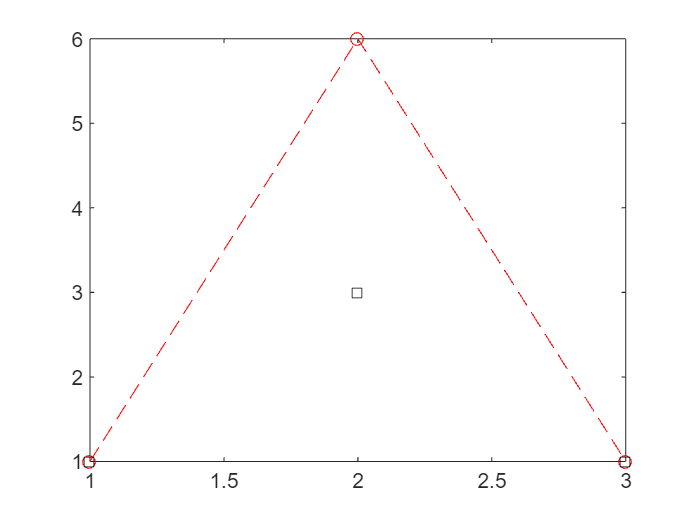

hold on
plot(s(:,2),"ks")

hold on 이런건 명령어로, 한번 입력 시 계속 실행됨.

x축은 자동으로 그려짐